# Lab 04

# Machine Learning 

## SNS EE/CE 252L/251L-T2

Name: M Shees Abbas

ID: ma11212

# Task 1

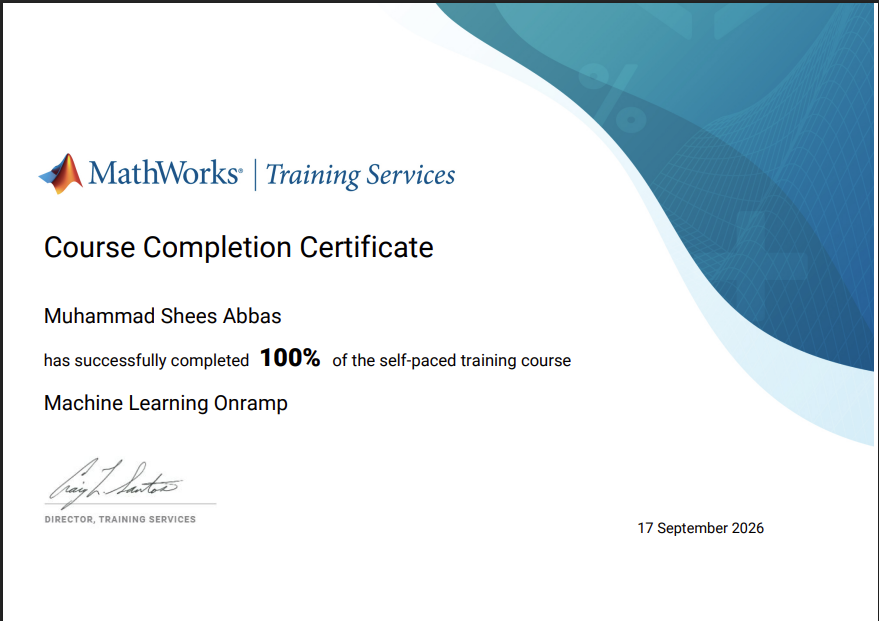

# Task 2

## step 1

data = readtable("student_data.xlsx");
disp(head(data, 5));

    StudyHours    Attendance    AssignmentScore     Result 
    __________    __________    _______________    ________

       1.5            94              65           {'Pass'}
       2.8            36              83           {'Pass'}
       4.2            68              59           {'Fail'}
       1.2            38              64           {'Pass'}
       0.5            78              48           {'Fail'}



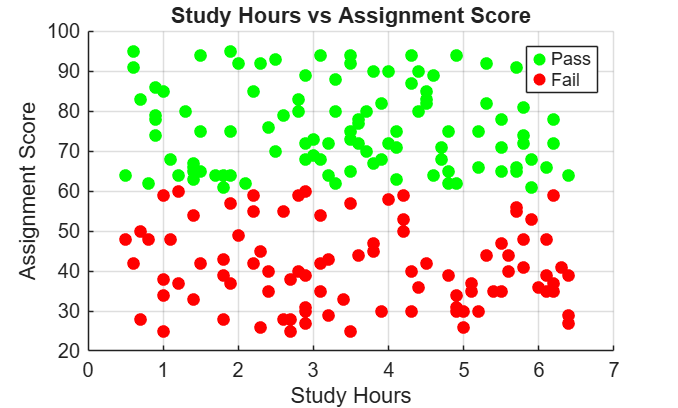

passrow = strcmp(data.Result, 'Pass');
failrow = strcmp(data.Result, 'Fail');
figure;
scatter(data.StudyHours(passrow), data.AssignmentScore(passrow), 40, 'g', 'filled');
hold on;
scatter(data.StudyHours(failrow), data.AssignmentScore(failrow), 40, 'r', 'filled');
hold off;
xlabel('Study Hours');
ylabel('Assignment Score');
title('Study Hours vs Assignment Score');
legend('Pass','Fail');
grid on;

we used the scatter function to plot the graph because we didnt want a continious graph because we are not ploting these against time, and both of the components are discrete

## step 2

StudyHours = data.StudyHours;
Attendance = data.Attendance;
AssignmentScore = data.AssignmentScore;
features = [StudyHours, Attendance, AssignmentScore];
labels = data.Result;

## step 3

featuresNorm = normalize(features, "zscore"); 

## step 4

rng(42);
numStudents = size(featuresNorm, 1);
shuffledIndices = randperm(numStudents);
trainCount = round(0.8 * numStudents);

XTrain = featuresNorm(shuffledIndices(1:trainCount), :);
yTrain = labels(shuffledIndices(1:trainCount));
XTest = featuresNorm(shuffledIndices(trainCount+1:end), :);
yTest = labels(shuffledIndices(trainCount+1:end));

## step 5


logisticModel = fitcsvm(XTrain, yTrain);

Unrecognized function or variable 'fitcsvm'.

fitcsvm requires Statistics and Machine Learning Toolbox.


predLogistic = predict(logisticModel, XTest);
accuracyLogistic = mean(strcmp(predLogistic, yTest)) * 100;
fprintf('Logistic Regression Accuracy: %.1f%%\n', accuracyLogistic);
confMatrixLogistic = confusionmat(yTest, predLogistic);
disp('Confusion Matrix:');
disp(confMatrixLogistic);

## step 6

treeModel = fitctree(XTrain, yTrain);
predTree = predict(treeModel, XTest);
accuracyTree = mean(strcmp(predTree, yTest)) * 100;
fprintf('Decision Tree Accuracy: %.1f%%\n', accuracyTree);
confMatrixTree = confusionmat(yTest, predTree);
disp('Confusion Matrix:');
disp(confMatrixTree);

forestModel = TreeBagger(30, XTrain, yTrain, 'Method', 'classification');
predForest = predict(forestModel, XTest);
predForest = strtrim(predForest);
accuracyForest = mean(strcmp(predForest, yTest)) * 100;
fprintf('Random Forest Accuracy: %.1f%%\n', accuracyForest);
confMatrixForest = confusionmat(yTest, predForest);
disp('Confusion Matrix:');
disp(confMatrixForest);

svmModel = fitcsvm(XTrain, yTrain);
predSVM = predict(svmModel, XTest);
accuracySVM = mean(strcmp(predSVM, yTest)) * 100;
fprintf('SVM Accuracy: %.1f%%\n', accuracySVM);
confMatrixSVM = confusionmat(yTest, predSVM);
disp('Confusion Matrix:');
disp(confMatrixSVM);

## step 7

[bestAccuracy, bestIndex] = max([accuracyLogistic, accuracyTree, accuracyForest, accuracySVM]);
modelNames = {'Logistic Regression', 'Decision Tree', 'Random Forest', 'SVM'};
fprintf('\nBest Model: %s with %.1f%% accuracy\n', modelNames{bestIndex}, bestAccuracy);

## step 8

fprintf('\n=== TEST NEW STUDENT ===\n');
newStudent = [5, 85, 78];
newStudentNorm = (newStudent - mean(features)) ./ std(features);
if bestIndex == 1
    prediction = predict(logisticModel, newStudentNorm);
elseif bestIndex == 2
    prediction = predict(treeModel, newStudentNorm);
elseif bestIndex == 3
    prediction = predict(forestModel, newStudentNorm);
    prediction = strtrim(prediction);
else
    prediction = predict(svmModel, newStudentNorm);
end

fprintf('New Student: Hours=%d, Attendance=%d%%, Score=%d\n', newStudent(1), newStudent(2), newStudent(3));
fprintf('Predicted Result: %s\n', prediction{1});